clc
clear

disp("Initilization Procedure")

Initilization Procedure


model.Parameters
param = control.calculateOperatingPoint(param);

Calculate Operating Point for T_a = 293.150000 [K]

param = model.calculateModel(param);

Calculate bilinear model matrices
Calculate linearisation decoupled
Calculate linearisation coupled
Testing controlability
Testing T_ref


## Design procedure 1

param.ctrl.Ks = control.DesignProcedure1(param,0);

Evaluation of design procedure 1 
Q is positive definite


ans =     0.3021    0.3034    0.3034    0.3034    0.7871    0.7871    0.7871    0.7884    2.0153    2.0153    2.0153    2.0161


R is positive definite


ans = 1.0e+03 *

    0.0292    0.0401    0.0462    0.1149    0.2445    0.2718    0.2776    0.2900    0.3183    0.3541    0.4120    1.0937


Gamma is found to be:


ans = 119.1575

Eigenvalues of the decoupled systems are all negative 


ans =   -1.2382 + 4.0460i  -1.2382 - 4.0460i  -0.2810 + 0.0000i  -1.2415 + 4.0904i  -1.2415 - 4.0904i  -0.2806 + 0.0000i  -1.2382 + 4.0460i  -1.2382 - 4.0460i  -0.2810 + 0.0000i  -1.2382 + 4.0460i  -1.2382 - 4.0460i  -0.2810 + 0.0000i


Eigenvalues of the coupled systems are all negative 


ans =   -0.7633 + 5.6104i  -0.7633 - 5.6104i  -0.4591 + 6.3840i  -0.4591 - 6.3840i  -0.3645 + 6.6218i  -0.3645 - 6.6218i  -0.3397 + 6.6635i  -0.3397 - 6.6635i  -0.2748 + 0.0000i  -0.2731 + 0.0000i  -0.2726 + 0.0000i  -0.2727 + 0.0000i


s = tf('s');
K = blkdiag(param.ctrl.Ks(:,:,1),param.ctrl.Ks(:,:,2),param.ctrl.Ks(:,:,3),param.ctrl.Ks(:,:,4));
M = K * eye(12)/(s * eye(12) - (param.model.A + param.model.B * K * eye(12)) )*param.model.B;

Defines a logspace to investigate the values over

W = logspace(-1,3,400);

Calculates the singular values of M evaluated at the freqiencies W

SV = sigma(M, W);

Calculates the spectral radius

spectral = zeros(1,length(W));
Ms = freqresp(M,W);
for i=1:length(W)   
    spectral(i) = abs(eigs(Ms(:,:,i),1));
end

Calculates the SSV

[bounds,muinfo]  = mussv(frd(M,W),[4,0],'an');

Points completed: 400/400


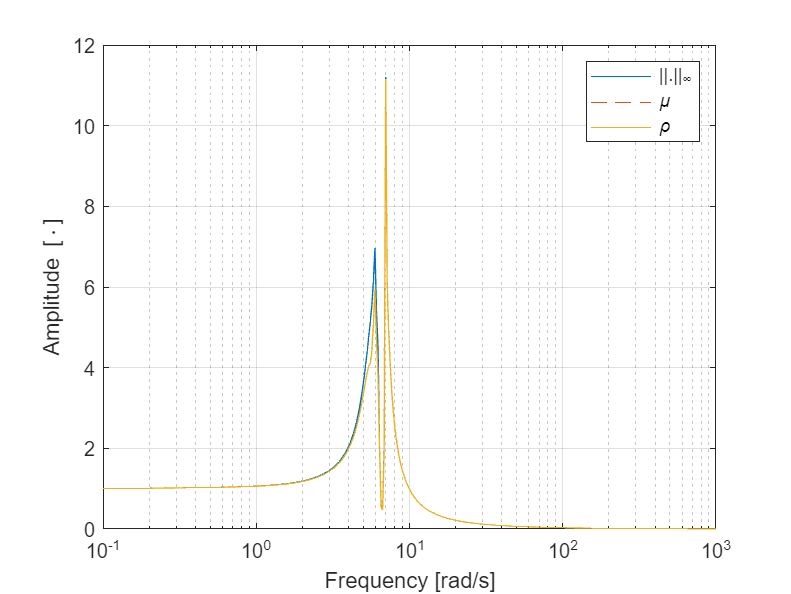

[VDelta,VSigma,VLmi] = mussvextract(muinfo);
upperBound = bounds(1).ResponseData(:);

figure()
semilogx(W,max(SV),W,upperBound,'--',W,spectral)
xlabel("Frequency [rad/s]")
ylabel("Amplitude [\cdot]")
legend('||.||_\infty', '\mu', '\rho')
grid on
saveas(gcf,'Images/Examination_Structure_DP1','epsc')

## Design procedure 2 with gamma = 1

param.ctrl.Ks = control.DesignProcedure2(param,0,1);

Evaluation of design procedure 2 
Q is positive definite


ans =     0.0015    0.0015    0.0015    0.0016    0.1684    0.1689    0.1693    0.1695    4.1608    4.6637    4.7502    4.8541


Gamma is found to be:


ans = 1

Eigenvalues of the decoupled systems are all negative 


ans =    -4.0059   -0.0311   -0.0000   -4.0442   -0.0312   -0.0000   -4.0059   -0.0311   -0.0000   -4.0058   -0.0311   -0.0000


Eigenvalues of the coupled systems are all negative 


ans =    -4.0442   -4.0059   -4.0059   -4.0058   -0.0311   -0.0312   -0.0311   -0.0311   -0.0000   -0.0000   -0.0000   -0.0000


s = tf('s');
K = blkdiag(param.ctrl.Ks(:,:,1),param.ctrl.Ks(:,:,2),param.ctrl.Ks(:,:,3),param.ctrl.Ks(:,:,4));
M = K * eye(12)/(s * eye(12) - (param.model.A + param.model.B * K * eye(12)) )*param.model.B;

Defines a logspace to investigate the values over

W = logspace(-1,3,400);

Calculates the singular values of M evaluated at the freqiencies W

SV = sigma(M, W);

Calculates the spectral radius

spectral = zeros(1,length(W));
Ms = freqresp(M,W);
for i=1:length(W)   
    spectral(i) = abs(eigs(Ms(:,:,i),1));
end

Calculates the SSV

[bounds,muinfo]  = mussv(frd(M,W),[4,0],'an');

Points completed: 400/400


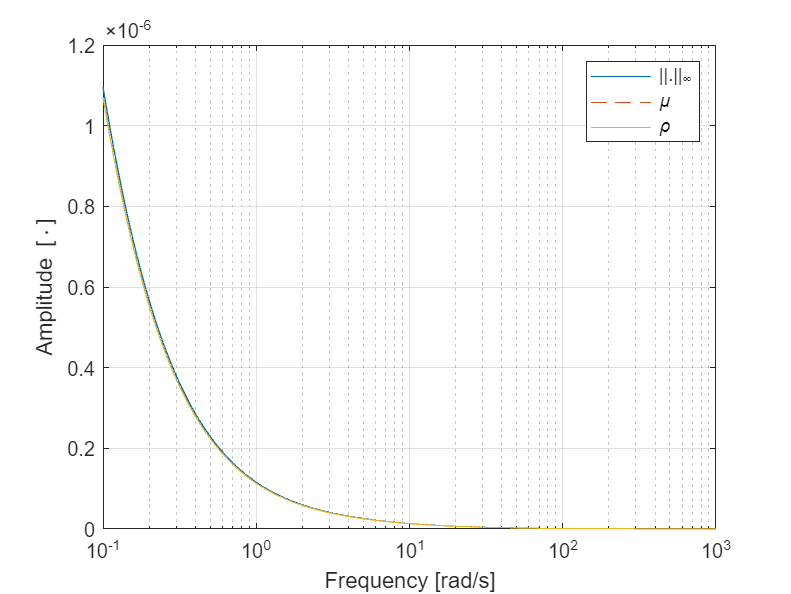

[VDelta,VSigma,VLmi] = mussvextract(muinfo);
upperBound = bounds(1).ResponseData(:);

figure()
semilogx(W,max(SV),W,upperBound,'--',W,spectral)
xlabel("Frequency [rad/s]")
ylabel("Amplitude [\cdot]")
legend('||.||_\infty', '\mu', '\rho')
grid on
saveas(gcf,'Images/Examination_Structure_DP2','epsc')

## Design procedure 2 with gamma as a variable

param.ctrl.Ks = control.DesignProcedure2(param,0,0);

Evaluation of design procedure 2 
Q is positive definite


ans =     0.0014    0.0014    0.0014    0.0082    0.1780    0.1794    0.1794    0.1820    3.0391    4.1899    4.2894    4.3188


Gamma is found to be:


ans = 1.0203

Eigenvalues of the decoupled systems are all negative 


ans =    -5.8861   -3.7193   -0.0473  -35.3607   -4.0279   -0.0231  -39.0341   -3.9902   -0.0230  -31.9229   -3.9896   -0.0225


Eigenvalues of the coupled systems are all negative 


ans =   -90.8194  -80.2837  -62.6284  -12.0194   -3.8636   -4.0289   -3.9907   -3.9912   -0.0473   -0.0225   -0.0231   -0.0230


s = tf('s');
K = blkdiag(param.ctrl.Ks(:,:,1),param.ctrl.Ks(:,:,2),param.ctrl.Ks(:,:,3),param.ctrl.Ks(:,:,4));
M = K * eye(12)/(s * eye(12) - (param.model.A + param.model.B * K * eye(12)) )*param.model.B;

Defines a logspace to investigate the values over

W = logspace(-1,3,400);

Calculates the singular values of M evaluated at the freqiencies W

SV = sigma(M, W);

Calculates the spectral radius

spectral = zeros(1,length(W));
Ms = freqresp(M,W);
for i=1:length(W)   
    spectral(i) = abs(eigs(Ms(:,:,i),1));
end

Calculates the SSV

[bounds,muinfo]  = mussv(frd(M,W),[4,0],'an');

Points completed: 400/400


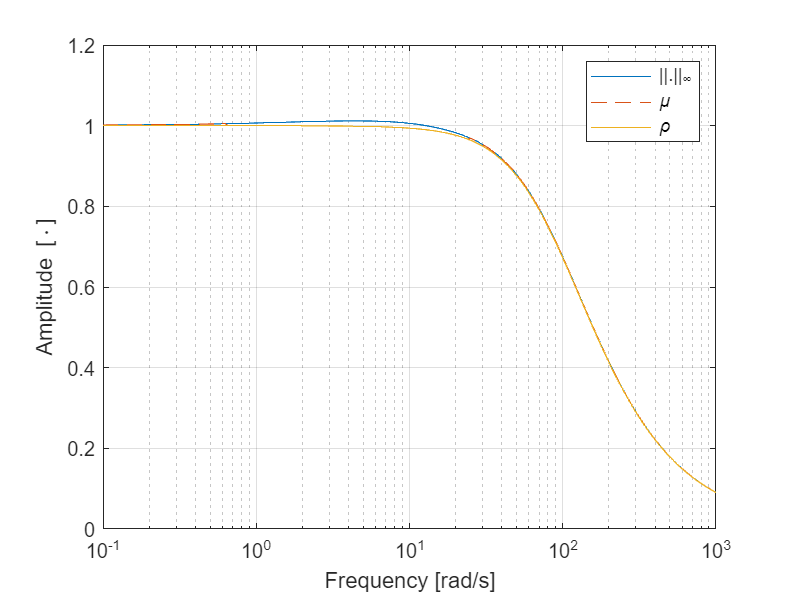

[VDelta,VSigma,VLmi] = mussvextract(muinfo);
upperBound = bounds(1).ResponseData(:);

figure()
semilogx(W,max(SV),W,upperBound,'--',W,spectral)
xlabel("Frequency [rad/s]")
ylabel("Amplitude [\cdot]")
legend('||.||_\infty', '\mu', '\rho')
grid on
saveas(gcf,'Images/Examination_Structure_DP2_Unboundgamma','epsc')

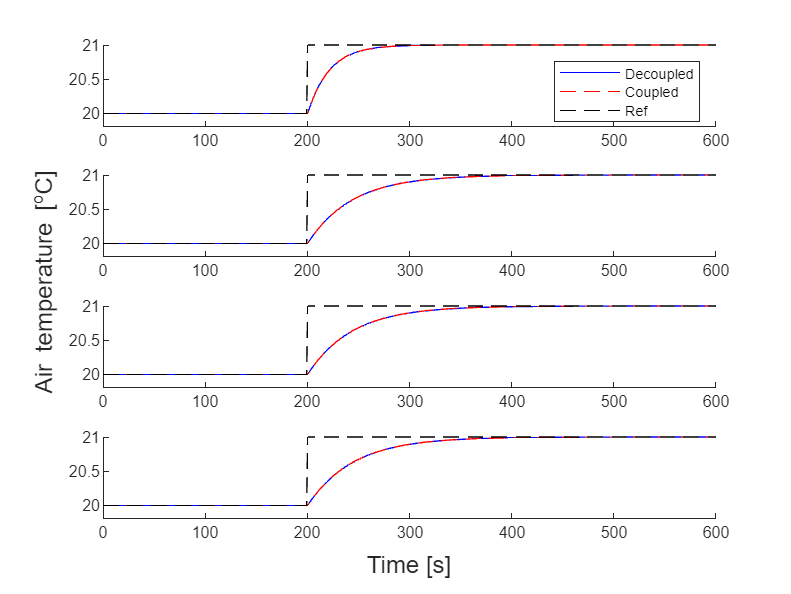

util.SimulateStep(param,"Examination_Structure_DP2_Unboundgamma_step",1);